%clc; clear all; close all;

xpos1 = out.data.signals(1).values(:,3);
xpos1 = reshape(xpos1, [1, size(xpos1, 1)]);
ypos1 = out.data.signals(1).values(:,4);
ypos1 = reshape(ypos1, [1, size(ypos1, 1)]);
th1 = out.data.signals(1).values(:,5);
th1 = reshape(th1, [1, size(th1, 1)]);

xpos2 = out.data.signals(2).values(:,3);
xpos2 = reshape(xpos2, [1, size(xpos2, 1)]);
ypos2 = out.data.signals(2).values(:,4);
ypos2 = reshape(ypos2, [1, size(ypos2, 1)]);
th2 = out.data.signals(2).values(:,5);
th2 = reshape(th2, [1, size(th2, 1)]);

xpos3 = out.data.signals(3).values(:,3);
xpos3 = reshape(xpos3, [1, size(xpos3, 1)]);
ypos3 = out.data.signals(3).values(:,4);
ypos3 = reshape(ypos3, [1, size(ypos3, 1)]);
th3 = out.data.signals(3).values(:,5);
th3 = reshape(th3, [1, size(th3, 1)]);

xref = out.data.signals(1).values(:,1);
xref = reshape(xref, [1, size(xref, 1)]);
yref = out.data.signals(1).values(:,2);
yref = reshape(yref, [1, size(yref, 1)]);

consensus = out.consensus.signals.values;
time = out.tout.';
enables1 = out.enables.signals(1).values;
enables1 = ~enables1;
en1 = time(find(enables1, 1, 'first'));

enables2 = out.enables.signals(2).values;
enables2 = ~enables2;
en2 = time(find(enables2, 1, 'first'));

enables3 = out.enables.signals(3).values;
enables3 = ~enables3;
en3 = time(find(enables3, 1, 'first'));

n = numel(xpos1);
min_window = -12;
max_window = 12;
tick_step = 4;
bound = 2;


figure
xlim([0 10])
ylim([min_window max_window])
box on;
grid on;
hold on;
legend on;

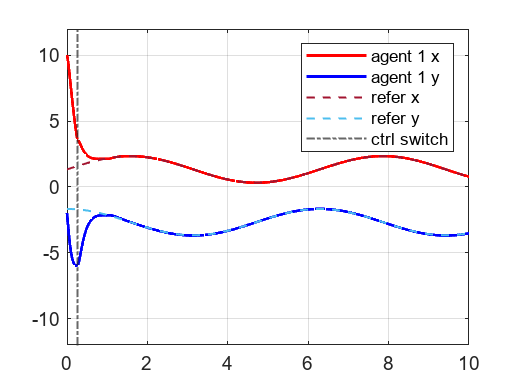

plot(time, xpos1,'DisplayName','agent 1 x', LineWidth=1.5, Color='r');
plot(time, ypos1,'DisplayName','agent 1 y', LineWidth=1.5, Color='b');
plot(time, xref,'DisplayName','refer x', LineWidth=1, LineStyle='--', Color="#A2142F");
plot(time, yref,'DisplayName','refer y', LineWidth=1, LineStyle='--', Color="#4DBEEE");
xline(en1, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");


figure
xlim([0 10])
ylim([min_window max_window])
box on;
grid on;
hold on;
legend on;

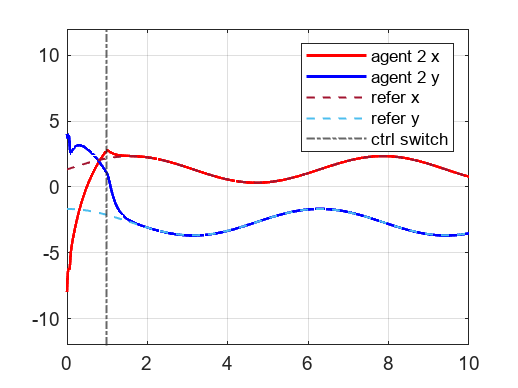

plot(time, xpos2,'DisplayName','agent 2 x', LineWidth=1.5, Color='r');
plot(time, ypos2,'DisplayName','agent 2 y', LineWidth=1.5, Color='b');
plot(time, xref,'DisplayName','refer x', LineWidth=1, LineStyle='--', Color="#A2142F");
plot(time, yref,'DisplayName','refer y', LineWidth=1, LineStyle='--', Color="#4DBEEE");
xline(en2, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");


figure
xlim([0 10])
ylim([min_window max_window])
box on;
grid on;
hold on;
legend on;

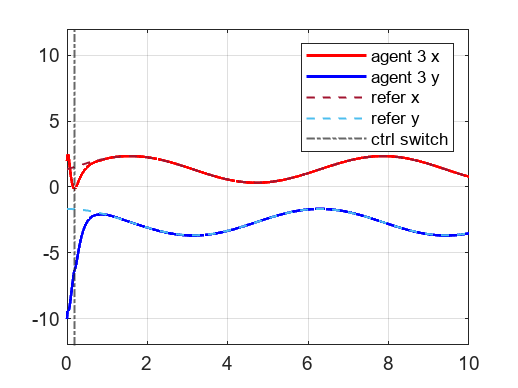

plot(time, xpos3,'DisplayName','agent 3 x', LineWidth=1.5, Color='r');
plot(time, ypos3,'DisplayName','agent 3 y', LineWidth=1.5, Color='b');
plot(time, xref,'DisplayName','refer x', LineWidth=1, LineStyle='--', Color="#A2142F");
plot(time, yref,'DisplayName','refer y', LineWidth=1, LineStyle='--', Color="#4DBEEE");
xline(en3, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");

figure
box on;
grid on;
hold on;
legend on;

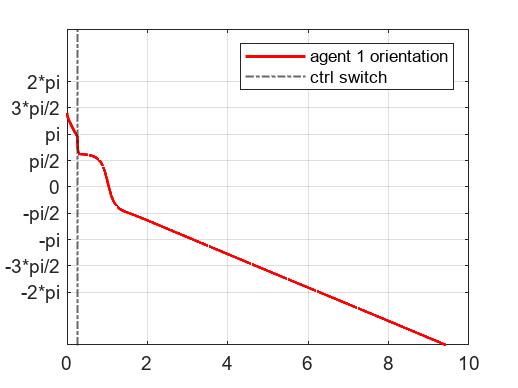


xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})

plot(time, th1,'DisplayName','agent 1 orientation', LineWidth=1.5, Color='r');
xline(en1, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");


figure
box on;
grid on;
hold on;
legend on;

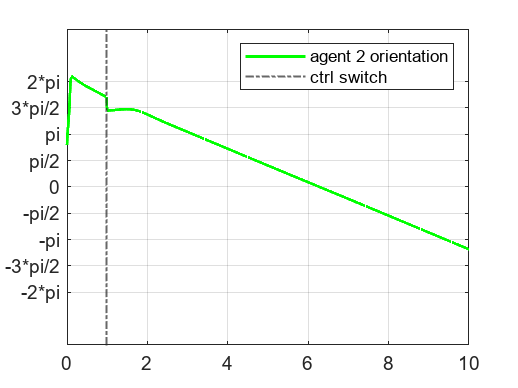


xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})

plot(time, th2,'DisplayName','agent 2 orientation', LineWidth=1.5, Color='g');
xline(en2, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");


figure
box on;
grid on;
hold on;
legend on;

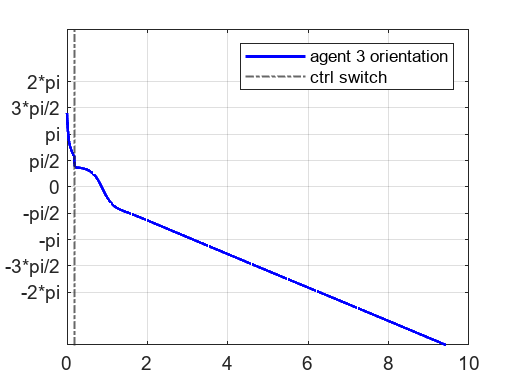


xlim([0 10])
ylim([-3*pi 3*pi])
set(gca,'YTick',-2*pi:pi/2:2*pi) 
set(gca,'YTickLabel',{'-2*pi','-3*pi/2','-pi','-pi/2','0','pi/2','pi','3*pi/2','2*pi'})

plot(time, th3,'DisplayName','agent 3 orientation', LineWidth=1.5, Color='b');
xline(en3, 'DisplayName','ctrl switch', LineWidth=1, LineStyle="-.");

STATIC PLOT

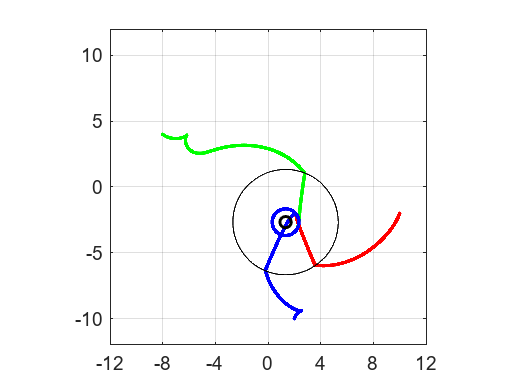


figure
axis equal
box on;
grid on;
xlim([min_window max_window])
ylim([min_window max_window])

xticks(min_window:4:max_window)
hold on

scatter(xpos1,ypos1, 32, '.r');
scatter(xpos2,ypos2, 32, '.g');
scatter(xpos3,ypos3, 32, '.b');
scatter(consensus(1),consensus(2), 32, 'ok', 'LineWidth',1.5);
circle(consensus(1),consensus(2),4);

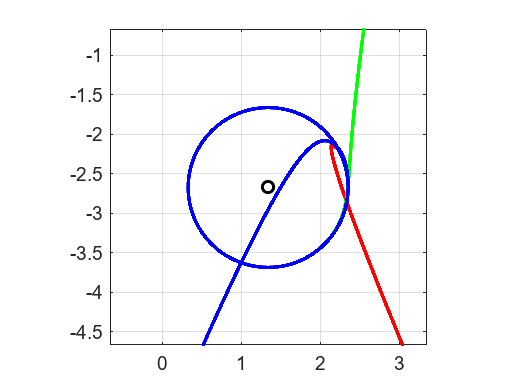

figure
axis equal
box on
hold on
grid on


xlim([consensus(1)-bound consensus(1)+bound])
ylim([consensus(2)-bound consensus(2)+bound])

scatter(xpos1,ypos1, 32, '.r');
scatter(xpos2,ypos2, 32, '.g');
scatter(xpos3,ypos3, 32, '.b');
scatter(consensus(1),consensus(2), 32, 'ok', 'LineWidth',1.5)

DYNAMIC PLOT

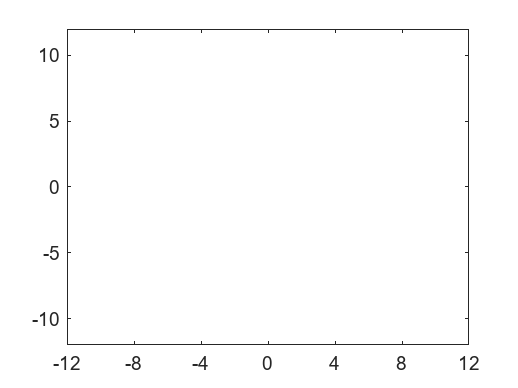

figure
box on
xlim([min_window max_window])
ylim([min_window max_window])
xticks(min_window:4:max_window)
hold on
for i = 1:5:1000
    a = plot(xpos1(i),ypos1(i), '.r');
    b = plot(xpos2(i),ypos2(i), '.g');
    c = plot(xpos3(i),ypos3(i), '.b');
    
    pause(0.05)
    delete(a)
    delete(b)
    delete(c)
end

figure
hold on
box on
xlim([min_window max_window])
ylim([min_window max_window])
xticks(min_window:4:max_window)

def1 = polyshape([0 0 1 1],[1 0 0 1]);
buffer_sz = 2;
buffer1 = repmat(def1, 1, buffer_sz);
pgon1 = nsidedpoly(3,'Center',[xpos1(1) ypos1(1)],'SideLength',1);
pgon1 = rotate(pgon1,th1(1)*180/pi -90, [xpos1(1) ypos1(1)]);
t = plot(buffer1(1), 'FaceColor','r');
dels1 = repmat(t, 1, buffer_sz);
for j = 1:buffer_sz
        delete(dels1(j));
end

def2 = polyshape([0 0 1 1],[1 0 0 1]);
buffer2 = repmat(def2, 1, buffer_sz);
pgon2 = nsidedpoly(3,'Center',[xpos2(1) ypos2(1)],'SideLength',1);
pgon2 = rotate(pgon2,th2(1)*180/pi -90, [xpos2(1) ypos2(1)]);
t = plot(buffer2(1), 'FaceColor','r');
dels2 = repmat(t, 1, buffer_sz);
for j = 1:buffer_sz
        delete(dels2(j));
end

def3 = polyshape([0 0 1 1],[1 0 0 1]);
buffer3 = repmat(def3, 1, buffer_sz);
pgon3 = nsidedpoly(3,'Center',[xpos3(1) ypos3(1)],'SideLength',1);
pgon3 = rotate(pgon3,th3(1)*180/pi -90, [xpos3(1) ypos3(1)]);
t = plot(buffer3(1), 'FaceColor','r');
dels3 = repmat(t, 1, buffer_sz);
for j = 1:buffer_sz
        delete(dels3(j));
end


for i = 1:5:1000
    pgon1 = nsidedpoly(3,'Center',[xpos1(i) ypos1(i)],'SideLength',1);
    pgon1 = rotate(pgon1,th1(i)*180/pi -90, [xpos1(i) ypos1(i)]);

    pgon2 = nsidedpoly(3,'Center',[xpos2(i) ypos2(i)],'SideLength',1);
    pgon2 = rotate(pgon2,th2(i)*180/pi -90, [xpos2(i) ypos2(i)]);

    pgon3 = nsidedpoly(3,'Center',[xpos3(i) ypos3(i)],'SideLength',1);
    pgon3 = rotate(pgon3,th3(i)*180/pi -90, [xpos3(i) ypos3(i)]);

    for j = 1:buffer_sz
        if ( i - j > 1)
            dels1(j) = plot(buffer1(j), 'FaceColor','r');
        end
    end

    for j = 1:buffer_sz
        if ( i - j > 1)
            dels2(j) = plot(buffer2(j), 'FaceColor','g');
        end
    end

    for j = 1:buffer_sz
        if ( i - j > 1)
            dels3(j) = plot(buffer3(j), 'FaceColor','b');
        end
    end

    h1 = plot(pgon1, 'FaceColor','r');
    h2 = plot(pgon2, 'FaceColor','g');
    h3 = plot(pgon3, 'FaceColor','b');
    pause(0.05)

    delete(h1); delete(h2); delete(h3);
    
    for j = 2:buffer_sz
        buffer1(j) = buffer1(j-1);
    end

    for j = 2:buffer_sz
        buffer2(j) = buffer2(j-1);
    end

    for j = 2:buffer_sz
        buffer3(j) = buffer3(j-1);
    end

    buffer1(1) = pgon1; buffer2(1) = pgon2; buffer3(1) = pgon3;
    
    for j = 1:buffer_sz
        delete(dels1(j));
    end

    for j = 1:buffer_sz
        delete(dels2(j));
    end

    for j = 1:buffer_sz
        delete(dels3(j));
    end
end

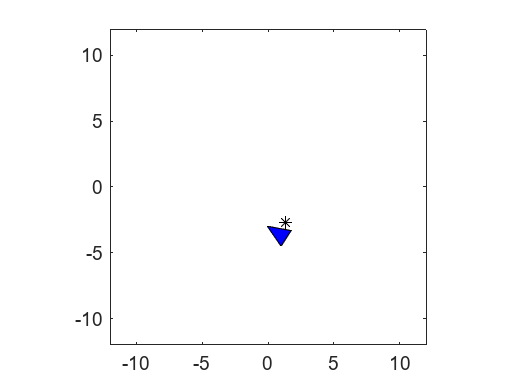

a = [-0.3536 -0.3536]';
b = [.5 0]';
c = [-0.3536 0.3536]';
P = 2*[a b c];
p1 = [];
p2 = [];
p3 = [];

figure
plot(consensus(1), consensus(2), '*k')
hold on

for i = 1:50:length(xpos1)
    delete(p1)
    
    x1 = xpos1(i);
    y1 = ypos1(i);
    theta1 = th1(i);
    R = [ cos(theta1) -sin(theta1); sin(theta1) cos(theta1)];
    Prot = R*P;
    Prot_trasl = Prot + [ones(1,3)*x1; ones(1,3)*y1];
    p1 = patch(Prot_trasl(1,:),Prot_trasl(2,:),'r');

    delete(p2)
    
    x2 = xpos2(i);
    y2 = ypos2(i);
    theta2 = th2(i);
    R = [ cos(theta2) -sin(theta2); sin(theta2) cos(theta2)];
    Prot = R*P;
    Prot_trasl = Prot + [ones(1,3)*x2; ones(1,3)*y2];
    p2 = patch(Prot_trasl(1,:),Prot_trasl(2,:),'g');
   
    delete(p3)
    
    x3 = xpos3(i);
    y3 = ypos3(i);
    theta3 = th3(i);
    R = [ cos(theta3) -sin(theta3); sin(theta3) cos(theta3)];
    Prot = R*P;
    Prot_trasl = Prot + [ones(1,3)*x3; ones(1,3)*y3];
    p3 = patch(Prot_trasl(1,:),Prot_trasl(2,:),'b');
   
axis square
xlim([-12.0 12.0])
ylim([-12.0 12.0])
    drawnow
    
end

function circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(x+xp,y+yp, LineWidth=0.7, Color='k');
end